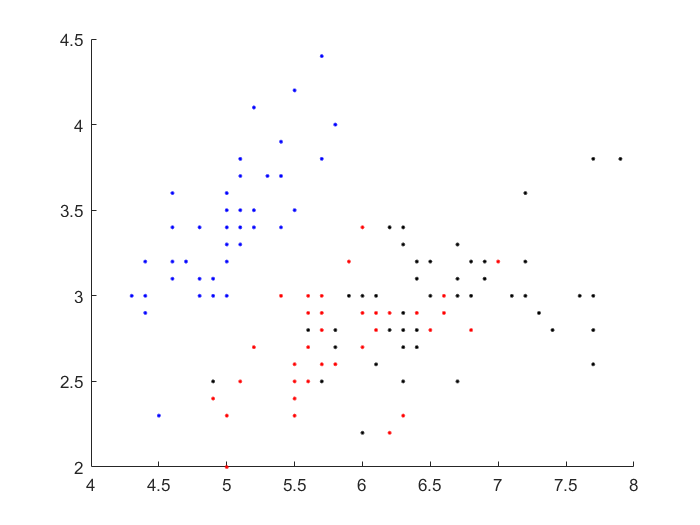

% 读入 iris 数据
x = iris_dataset;
% 显示前两维
figure(1)
hold on
plot(x(1,1:50),x(2,1:50),'b.','LineWidth',1.5);
plot(x(1,51:100),x(2,51:100),'r.','LineWidth',1.5);
plot(x(1,101:150),x(2,101:150),'k.','LineWidth',1.5);

% 标签
gnd = [ones(1,50),ones(1,50)*2,ones(1,50)*3];
seq = randperm(150);
Train = x(:,seq(1:100));
gnd_T = gnd(seq(1:100));
Test = x(:,seq(101:end));
gnd_Test = gnd(seq(101:end));
[pw,my_m,my_std] = my_nb(Train,gnd_T);
[post_p,test_lab] = my_testnb(Test,pw,my_m,my_std,3,4);
right = gnd_Test == test_lab;
rate = sum(right)/length(gnd_Test);
disp(['NB Accuracy:' num2str(rate*100) '%']);

NB Accuracy:94%
